# Lab - 03

## Question 1

Matrices are generated of size n=4, with a = 2 and b = 5.

format long e;
n = 4; a = 2; b = 5;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      1.679652327273171e+00     1.164982427327790e-03     2.010455256620696e-01    -3.034871818782517e-01
                         0     1.538876458308379e+00     3.361073676771074e-02     2.854558629118028e-02
                         0                         0     1.621733269157259e+00    -2.505342817716897e-01
                         0                         0                         0     1.757521072575833e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      1.679652327273171e+00     1.164982427327789e-03     2.010455256620696e-01    -3.034871818782516e-01
                         0     1.538876458308379e+00     3.361073676771073e-02     2.854558629118028e-02
                         0                         0     1.621733269157259e+00    -2.505342817716897e-01
                         0                         0                         0     1.757521072575833e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      6.214204261499011e-17



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      4.578092683617720e-16


We see that norm(G - G_hat) is very small for all examples and so is A - G'G, which means mychol is working well.

format long e;
n = 5; a = 1; b = 8;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      2.014017551347323e+00    -1.636166863402616e-02    -5.100554992976671e-02    -4.407201070122804e-01    -2.461236540770252e-01
                         0     1.818696075599374e+00    -2.597527500756876e-03    -2.871622426977798e-01     6.687914603691959e-02
                         0                         0     1.828047594674504e+00    -3.557753619573286e-01     6.649708215414168e-02
                         0                         0                         0     2.607515041494688e+00    -2.462382066398457e-02
                         0                         0                         0                         0     1.835990562521264e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      2.014017551347323e+00    -1.636166863402616e-02    -5.100554992976671e-02    -4.407201070122804e-01    -2.461236540770252e-01
                         0     1.818696075599374e+00    -2.597527500756876e-03    -2.871622426977798e-01     6.687914603691958e-02
                         0                         0     1.828047594674504e+00    -3.557753619573285e-01     6.649708215414168e-02
                         0                         0                         0     2.607515041494688e+00    -2.462382066398458e-02
                         0                         0                         0                         0     1.835990562521264e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      5.551115123125783e-17



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      1.013972311822991e-15


format long e;
n = 6; a = 2; b = 7;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      1.935515670039282e+00     5.533072218620202e-02    -3.515950877835760e-01     1.334312295857561e-01    -2.219545029719787e-01     1.065933441477660e-01
                         0     2.265553509548719e+00    -2.619336999550032e-01     4.727509540000249e-01    -9.186224605665246e-02    -3.216852787652110e-01
                         0                         0     2.260153740069861e+00    -1.111808484446458e-01    -2.488555439938032e-01    -1.883818689596478e-01
                         0                         0                         0     2.003959904218970e+00    -2.217738922909816e-01     1.208774328065257e-01
                         0                         0                         0                         0     1.856183521632371e+00     3.447398808790877e-02
                         0                         0                         0                         0                         0     1.901308038716474e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      1.935515670039282e+00     5.533072218620202e-02    -3.515950877835761e-01     1.334312295857561e-01    -2.219545029719787e-01     1.065933441477660e-01
                         0     2.265553509548719e+00    -2.619336999550032e-01     4.727509540000249e-01    -9.186224605665246e-02    -3.216852787652110e-01
                         0                         0     2.260153740069861e+00    -1.111808484446458e-01    -2.488555439938032e-01    -1.883818689596478e-01
                         0                         0                         0     2.003959904218970e+00    -2.217738922909816e-01     1.208774328065257e-01
                         0                         0                         0                         0     1.856183521632371e+00     3.447398808790877e-02
                         0                         0                         0                         0                         0     1.901308038716475e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      4.487076655785183e-16



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      9.647157888284033e-16


Norms are small for above and below examples as well.

## Question 2

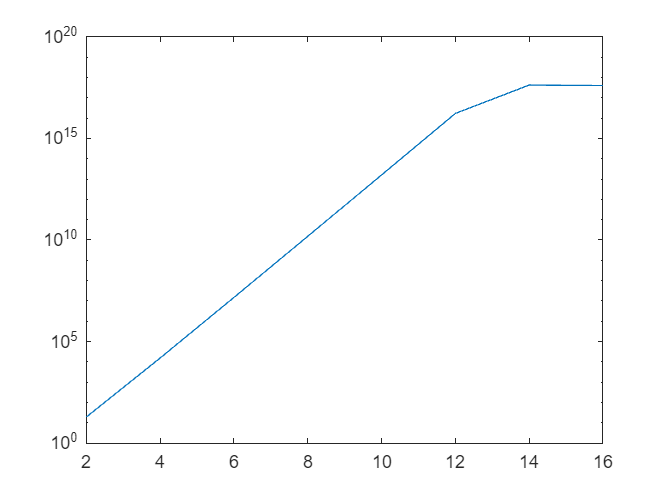

% 2-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H)];
end
semilogy(N,C)

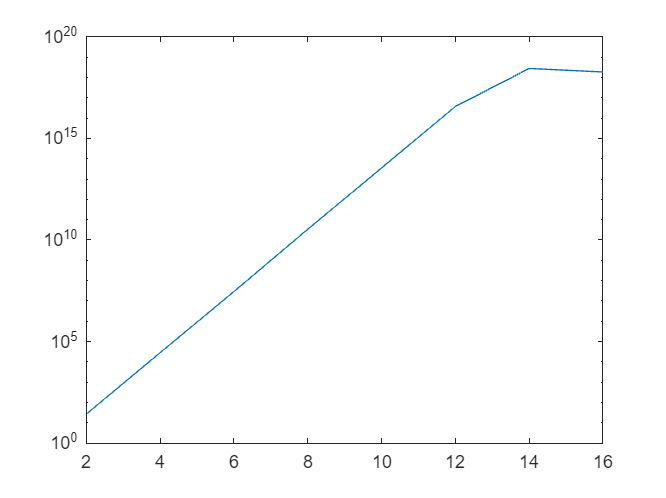


% 1-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H,1)];
end
semilogy(N,C)


% inf-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H,inf)];
end
semilogy(N,C)

From the graphs we observe that cond(H) vs n is linear on the semi-log y plot, which is plot() function with scale on y-axis as logarithmic base 10. We can say that the cond(H) depends on n exponentially and is increasing exponentially as the power or 10 with increasing n. Beyond 10^15, linearity is sort of lost and matrix becomes ill-conditioned and is nearly singular. 

## Question 3

format long e;
N = 8:2:12;
for n = N
    H = hilb(n);
    HI = invhilb(n);
    x = rand(n,1);
    b = H*x;
    % Using \
    x1 = H\ b;
    
    % Using inverse
    x2 = HI*b;
    
    % Using geppsolve
    x3 = geppsolve(H,b);
    

    fprintf('X for n = %d',n);
    arr = [x x1 x2 x3]
    
    disp('condition number and norms');
    arr = [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]
end

X for n = 8

arr =      7.342681079110888e-01     7.342681079102753e-01     7.342681079280737e-01     7.342681079102753e-01
     8.866990953365433e-01     8.866990954512199e-01     8.866990944370627e-01     8.866990954512199e-01
     1.026960670694603e-01     1.026960649554653e-01     1.026960611343384e-01     1.026960649554653e-01
     2.393740079800628e-01     2.393740218177287e-01     2.393740117549896e-01     2.393740218177287e-01
     2.207550021240017e-01     2.207549599885519e-01     2.207551002502441e-01     2.207549599885519e-01
     5.489708593518859e-01     5.489709243902882e-01     5.489708185195923e-01     5.489709243902882e-01
     6.927231843790242e-01     6.927231349841267e-01     6.927231252193451e-01     6.927231349841267e-01
     3.016338481439946e-01     3.016338628039466e-01     3.016338869929314e-01     3.016338628039466e-01


condition number and norms


arr =      1.525757548992251e+10     6.186187991206560e-08     8.406829735694630e-08     6.186187991206560e-08


X for n = 10

arr =      2.322653415063769e-02     2.322653337704983e-02     2.322653366718441e-02     2.322653337704983e-02
     9.179208287279472e-01     9.179208955435705e-01     9.179208353161812e-01     9.179208955435705e-01
     5.324441441147837e-01     5.324427212248903e-01     5.324414968490601e-01     5.324427212248903e-01
     6.021986755674135e-01     6.022116099748398e-01     6.022071838378906e-01     6.022116099748398e-01
     8.279747877410171e-01     8.279130953630373e-01     8.279724121093750e-01     8.279130953630373e-01
     9.615902038106534e-01     9.617597937206853e-01     9.617767333984375e-01     9.617597937206853e-01
     8.441600989782650e-01     8.438818537592179e-01     8.440856933593750e-01     8.438818537592179e-01
     4.753951196926158e-01     4.756640131008760e-01     4.757385253906250e-01     4.756640131008760e-01
     6.670494339349193e-01     6.669082658795868e-01     6.670379638671875e-01     6.669082658795868e-01
     1.139664289585366e-01     1.139974742745043e

condition number and norms


arr =      1.602477880438442e+13     2.126723885425839e-04     1.878422308619546e-04     2.126723885425839e-04


X for n = 12

arr =      5.245112036371808e-01     5.245112565704544e-01     5.245112385600805e-01     5.245112565704544e-01
     7.865318654646920e-01     7.865251612246552e-01     7.865285873413086e-01     7.865251612246552e-01
     7.603652600225171e-01     7.605758546949474e-01     7.605476379394531e-01     7.605758546949474e-01
     8.447618502742463e-01     8.418964975286675e-01     8.435058593750000e-01     8.418964975286675e-01
     6.523325277396274e-01     6.733068922575957e-01     6.762695312500000e-01     6.733068922575957e-01
     3.721301724835704e-01     2.801117009005655e-01     2.578125000000000e-01     2.801117009005655e-01
     2.069195774350707e-02     2.767002268390851e-01     3.125000000000000e-01     2.767002268390851e-01
     9.384366467353836e-01     4.756937484420256e-01     5.156250000000000e-01     4.756937484420256e-01
     8.711964202439317e-01     1.412954719605161e+00     1.187500000000000e+00     1.412954719605161e+00
     2.128687720280467e-01    -1.833798948730344e

condition number and norms


arr =      1.708620755565175e+16     3.817182328568360e-01     3.266845575019071e-01     3.817182328568360e-01


By computing x1, x2, and x3 for n = 8, 10, and 12 we see a significant loss of accuracy. Specifically, 10, 13 and all 16 digits were lost for n = 8, n = 10 and n = 12 respectively as indicated by the condition numbers.

The computed values of x1, x2, and x3 for each n exhibit similar levels of error, as indicated by their comparable order of magnitude and consistent mantissa variations.

This observation of loss of accuracy goes along with the theoretical predictions of the Rule-of-Thumb. Specifically, the relative error, expressed as ||x – x’||/||x||, is consistently less than or equal to 0.5 * 10^(-p). This indicates that the computed values (x’) agree with the true values (x) to at least p significant digits for all entries.

## Question 4

n=10;
H=hilb(n);
x = randn(n,1);
b = H*x;

x1= H \ b;
r = H*x1-b;

disp([norm(r)/norm(b) norm(x-x1)/norm(x)])

     3.250760870391776e-16     1.274058566900016e-05



norm(r)/norm(b)

ans =      3.250760870391776e-16


norm(x-x1)/norm(x)

ans =      1.274058566900016e-05


The magnitude of ||r||/||b|| does not necessarily correlate with the magnitude of ||x – x’||/||x||. In this specific instance, ||x – x’||/||x|| is significantly larger, approximately 10^(-5) compared to 10^(-17) for ||r||/||b||. This discrepancy highlights that a small ||r||/||b|| alone is insufficient to determine the proximity of x to x’.

## Question 5

rng('default');

N = [32, 64];
cond_nums = [];
gepp_errors = [];
gepp_ratios = [];
qr_errors = [];
qr_ratios = [];

for n = N
    x = rand(n, 1);
    
    W = Wilkinson(n);
    b = W * x;

    % using geppsolve
    x1 = geppsolve(W, b);
    

    cond_nums = [cond_nums; cond(W, inf)];
    gepp_errors = [gepp_errors; norm(x - x1, inf) / norm(x, inf)];
    gepp_ratios = [gepp_ratios; norm(W * x1 - b, inf) / norm(b, inf)];


    [Q, R] = qr(W);
    x_qr = colbackward(R, Q' * b);
    qr_errors = [qr_errors; norm(x - x_qr, inf) / norm(x, inf)];
    qr_ratios = [qr_ratios; norm(W * x_qr - b, inf) / norm(b, inf)];
end

T = table(N', cond_nums, gepp_errors, qr_errors, gepp_ratios, qr_ratios, ...
    'VariableNames', {'n', 'Condition_Number', 'GEPP_Error', 'QR_Error', 'GEPP_Ratio', 'QR_Ratio'});

disp(T);

             n                Condition_Number           GEPP_Error               QR_Error               GEPP_Ratio               QR_Ratio      
    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

    3.20000000000000e+01    3.20000000000000e+01    1.55614424824546e-09    3.88912668078808e-15    2.34242378177623e-10    5.15371969638552e-16
    6.40000000000000e+01    6.40000000000018e+01    3.57613958266690e+00    1.02954385192916e-14    2.32835225097688e-01    7.10945579929463e-16



a) The QR decomposition method showed significantly lower numerical errors compared to the Gaussian elimination with partial pivoting (GEPP) method. QR decomposition errors were on the order of 10^(-14) to 10^(-15), while GEPP errors were nearly 10^(-9) and 10^(0).

b) The Rule-of-Thumb accurately predicted the error behavior for the QR decomposition method. With t = 1 for both n = 32 and n = 64, the predicted forward error of s - t = 15 closely matched the actual computed errors. However, the accuracy of GEPP is overestimated by the Rule-of-Thumb. For n = 32, the observed error was on the order of 10^(-9), significantly larger than the predicted 10^(-16).

c) The QR decomposition method consistently produced lower infinity norm ratios for both n = 32 and n = 64, on the order of 10^(-16).

d) The QR decomposition method demonstrated backward stability, as supported by the computed data and Rule-of-Thumb analysis. In contrast, GEPP was found to be numerically unstable, indicating a lack of backward stability.

# **Functions **

function G = mychol(A)
    [n,~] = size(A);
    if A(1,1) <= 0
        error('Oops! Negative diagonol entry encountered');
    end
    
    G = zeros(n,n);
    g11 = sqrt(A(1,1));
    G(1,1) = g11;
    
    if n==1
        return;
    end
    b = A(1,2:n).';
    A_hat = A(2:n,2:n);
    g = G(1,2:n).';
    
    g = b/g11;
    
    G(1,2:n) = g.';
    G(2:n,2:n) = mychol(A_hat - g*g.');
    return;
end


function x = colbackward(U, b)
    [n, ~] = size(U);
    x = zeros(n, 1);
    for i = n:-1:1
        if U(i,i) ~= 0
            x(i) = b(i) / U(i,i);
        else
            error('Matrix is singular');
        end
        b(1:i-1) = b(1:i-1) - U(1:i-1,i) * x(i);
    end
end


function x = rowforward(L, b)
    [n, ~] = size(L);
    x = zeros(n, 1);
    for k = 1:n
        for j = 1:k-1
            b(k) = b(k) - L(k, j) * x(j);
        end
        if L(k,k) ~= 0
            x(k) = b(k) / L(k,k);
        else
            error('Matrix is singular');
        end
    end
end

function [L, U, p] = gepp(A)    
    [n, ~] = size(A);
    p = (1: n);
    for k = 1:n-1
        [~, ind] = max(abs(A(k: end, k)));
        ind = ind+k-1;
        
        if ind ~= k
            A([ind, k],:) = A([k, ind],:);
            p([ind, k]) = p([k, ind]);
        end
        
        if A(k,k) ~= 0
            A(k+1:n,k) = A(k+1:n,k) / A(k,k);
        end
        
        A(k+1:n, k+1:n) = A(k+1:n,k+1:n) - A(k+1:n,k)*A(k,k+1:n);
    end
    
    L = eye(n) + tril(A, -1);
    U = triu(A);
end

function [x] = geppsolve(A, b)
    [n, ~] = size(A);
    [L, U, p] = gepp(A);
    y = rowforward(L, b(p, :));
    x = colbackward(U, y);
end


function W = Wilkinson(n)
    W = (tril(ones(n)) .* -1) + (eye(n) .* 2);
    W(:, end) = 1;
end
